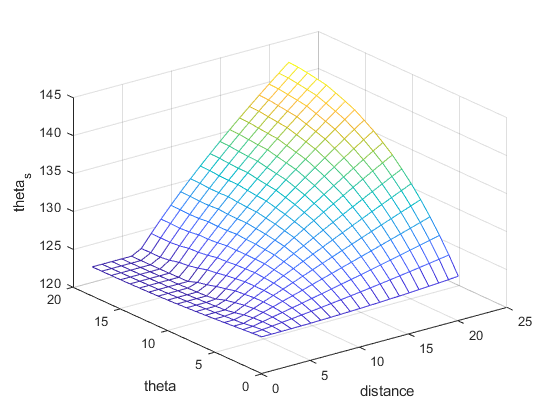

h_1=92.5;
h_2=74;
l_1=140;
l_2=150;
h_r=97.5;
h_s=22.3;
w_s=204.3;
l_s=72;
l_r=160;
d_w=31;             %% original value -> d_w = 45
r=248;
pi=3.141592;

%%initial angle = 47.0459(in straight pipe)

for theta = 0:90
    j= 253-50  ; %253
    for s = 0:j
        

        %%alpha=22.5
           equation= @(x) ((r+h_s-h_r+l_s*cos(x)+d_w/2*cos((5.625*s/j+(5.625-5.625*s/j)*theta/90)*pi/180) ...  
          )*cos(theta*pi/180))^2/r^2 + ...
          (tan(84.375*pi/180)*(l_s*cos(x)+d_w/2*cos((5.625*s/j+(5.625-5.625*s/j)*theta/90)*pi/180)...
          +r+h_s-h_r)*cos((90-theta)*pi/180) ...
          -(253-12*sin(theta*pi/180))+s+w_s+l_s*sin(x)+d_w/2*sin((5.625*s/j+(5.625-5.625*s/j)*theta/90)*pi/180)...
          +d_w/2*sin(((5.625*s/j-(5.625*s/j-5.625))*sin(theta*pi/180))*pi/180)*...
          (1-cos(((5.625*s/j-(5.625*s/j-5.625))*theta/90)*pi/180)...
          *tan(((5.625*s/j-(5.625*s/j-5.625))*theta/90)*pi/180))*sin(theta*pi/180))^2/(r/sin(5.625*pi/180))^2-1;
      
          
          b(theta+1,s+1)=fzero(equation,1)*180/pi+90;
%         if b(theta+1,s+1)>300 || b(theta+1,s+1)<0
%             b(theta+1,s+1)=b(theta+1,s+1);
%         % b(theta+1,j+1-s)=nan
%         end
    end
end

for theta=0:90
    for s=0:j
          deltad(theta+1,s+1)=(l_s*cos((b(theta+1,s+1)-90)*pi/180)+d_w/2* ...
          sin((90-10*s/j-(22.5-10*s/j)*sin(theta*pi/180))*pi/180) ...
          *sin(theta*pi/180)+r+h_s-h_r)* ...
          sin(theta*pi/180);
    end
end


%%% s=0, the start point values

for i=0:90
    distance(i+1)=248*sin(i*pi/180);
    y_distance(i+1)=distance(i+1)*tan(11.25*pi/180);
    fix_value(i+1)=round(y_distance(i+1));
end

for i=0:90
    if fix_value(i+1) ~= 0
            for k1=0:203-fix_value(i+1)
                b(i+1,204-k1)=b(i+1,204-k1-fix_value(i+1));
            end
            for k2=1:fix_value(i+1)
                b(i+1,k2)=b(i+1,1);
            end
    end
end

for theta=0:18
    for s=0:20
          real_theta(theta+1,s+1)=b(theta*5+1,s*10+4);
    end
end

mesh(real_theta);
xlabel 'distance'
ylabel 'theta'
zlabel 'theta_s'